clc, clear, close all;
addpath OTHER
addpath DATASET

display_points = 1000;
base_sample_rate = 1000;
frame_size = 1001;

# import data

filename_base = 'pianosync.wav';
[y,Fs] = audioread(filename_base); % 8kHz sample
base_sync_1k = SigConToBin(y(:, 1)', Fs, base_sample_rate);
base_sync_1k_base = double(base_sync_1k)-0.5;
base_sync_1k = base_sync_1k_base;

filename_EMG = 'opensignals_000780589b3a_2023-12-19_11-12-23.txt';
data = readmatrix(filename_EMG, 'Range', 4, 'Delimiter', '\t');
emg_sample_rate = 1000;
emg_sync_1k = ReadEMG(data, emg_sample_rate, base_sample_rate);

Align the datapoints

%[base_sync_1k, emg_sync_1k, actual_sample_rate] = FindSampleFreq(base_sync_1k, base_sample_rate, emg_sync_1k)
[emg_sync_1k, lag_emg] = Align(base_sync_1k, emg_sync_1k);
emg_sync_1k = emg_sync_1k(lag_emg: end);
base_sync_1k = base_sync_1k(lag_emg: end);

Cut to size

min_length = floor(min([length(emg_sync_1k) length(base_sync_1k)]));
emg_sync_1k = emg_sync_1k(1:min_length);
base_sync_1k = base_sync_1k(1:min_length);


Align the beginning

TODO: needs to be included in the Align function

[ emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
%shift the signal to the correct position
[~, max_start] = max(emg_corr_start);
max_start = floor((frame_size-max_start))+1

max_start =     22


if max_start < 0
    base_sync_1k = base_sync_1k(abs(max_start): end-abs(max_start));
else
    emg_sync_1k = emg_sync_1k(abs(max_start): end-abs(max_start));
end

Cut to size again

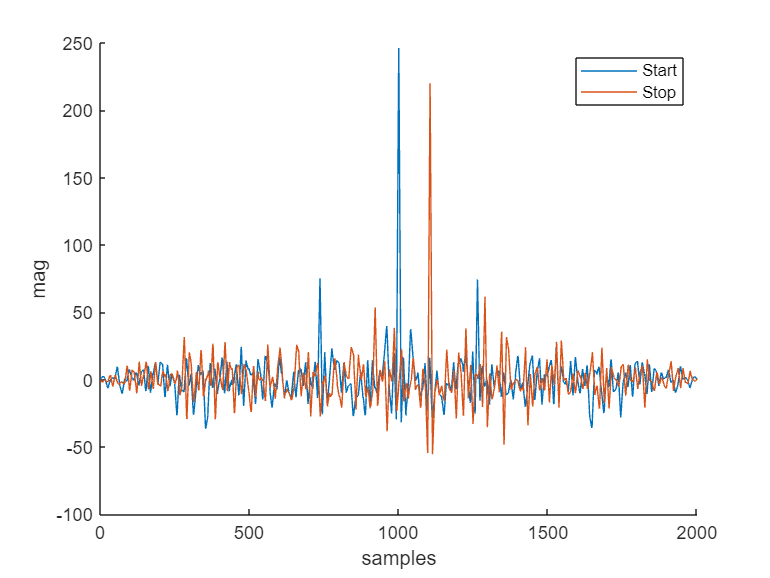

min_length = floor(min([length(emg_sync_1k) length(base_sync_1k)]));
emg_sync_1k = emg_sync_1k(1:min_length);
base_sync_1k = base_sync_1k(1:min_length);

[~, ~] = PlotCorrDrift(frame_size, base_sync_1k, emg_sync_1k)

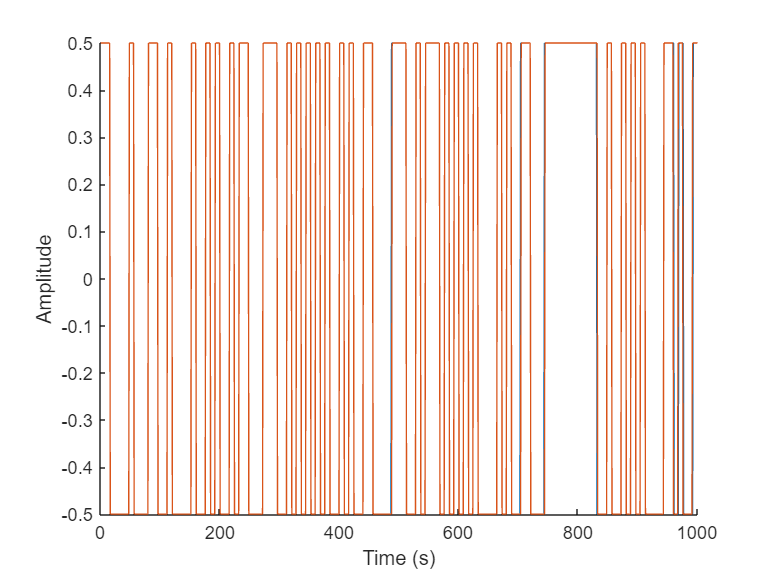


figure;
hold on
plot(base_sync_1k(1:display_points), "DisplayName","base");
plot(emg_sync_1k(1:display_points), "DisplayName","emg");
xlabel('Time (s)');
ylabel('Amplitude');
hold off


format longg

Find the original sample frequency

[base_sync_1k, emg_sync_1k, actual_sample_rate] = FindSampleFreq(base_sync_1k+0.5, base_sample_rate, emg_sync_1k)

base_sync_1k =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1


emg_sync_1k =          0.500304881260102          0.50034916970553         0.500330411564208         0.500341110193171         0.500334304198273         0.500338622402866         0.500343406662824         0.500323696052053         0.500368073335312          0.50028569681278         0.500424956552854         0.500202034591524         0.500549439040745         0.500002158544989         0.500924213892267         0.498939934221575        -0.501688415871823         -0.49976381836551        -0.500668074163033        -0.500130075666042        -0.500472368363034        -0.500253334522425        -0.500390472268438        -0.500309365911936        -0.500353748375551        -0.500333111872533        -0.500332875100835        -0.500332638357695        -0.500332401643142        -0.500332164957206        -0.500331928299911        -0.500331691671287        -0.500331455071362        -0.500331218500164         -0.50033098195772        -0.500330745444058        -0.500330508959206        -0.5003302725031

actual_sample_rate =           999.871131648226


[base_sync_1k, emg_sync_1k, actual_sample_rate] = FindSampleFreq(base_sync_1k, base_sample_rate, emg_sync_1k)

base_sync_1k =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1


emg_sync_1k =          0.500591258820856         0.500705216519935         0.500656929685459         0.500684515497787         0.500666880631721         0.500678238229567         0.500690127448124         0.500640070376827          0.50075329958069         0.500542643493999         0.500899295409439         0.500327714951354         0.501219395696477         0.499813212953705         0.502185388370039         0.497068286491783          -0.5041399223265        -0.499199982315662        -0.501526552703146        -0.500140205695268        -0.501023538055644        -0.500457353833175        -0.500812565809762        -0.500601885983771        -0.500717669531956        -0.500663354639388        -0.500663552737383        -0.500662516391067        -0.500662139559987        -0.500661409818544        -0.500660850678078         -0.50066025018921        -0.500659560220229        -0.500659154954764        -0.500658118816515        -0.500658351417014        -0.500656139291972        -0.5006586222371

actual_sample_rate =           999.797482647945


[base_sync_1k, emg_sync_1k, actual_sample_rate] = FindSampleFreq(base_sync_1k, base_sample_rate, emg_sync_1k)

base_sync_1k =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1


emg_sync_1k =           0.50081701476775         0.501083082411638         0.500970258034459         0.501034904992489         0.500993210428913          0.50102077729818          0.50104680237585         0.500932642181152         0.501193088048082          0.50070658659621          0.50153248218059          0.50020609363272         0.502279224234558         0.499003449679111         0.504543359095139         0.492534377973864        -0.509042977917547         -0.49757554289516         -0.50300257006091        -0.499759298901382        -0.501831354636414        -0.500499257748158        -0.501338020519977        -0.500838019072445        -0.501114878565773        -0.500982988632821        -0.500986918036307        -0.500982651758903        -0.500982783675055        -0.500980545882763        -0.500979473561908        -0.500978081493407        -0.500976162238957        -0.500976028593503        -0.500971868891649        -0.500975884831271        -0.500964030472976        -0.5009828729396

actual_sample_rate =           999.558162939689


[ emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
%shift the signal to the correct position
[~, max_start] = max(emg_corr_start);
max_start = floor((frame_size-max_start))+1

max_start =      1


cut to size

min_length = floor(min([length(emg_sync_1k) length(base_sync_1k)]))

min_length =       162813


emg_sync_1k = emg_sync_1k(1:min_length)

emg_sync_1k =           0.50081701476775         0.501083082411638         0.500970258034459         0.501034904992489         0.500993210428913          0.50102077729818          0.50104680237585         0.500932642181152         0.501193088048082          0.50070658659621          0.50153248218059          0.50020609363272         0.502279224234558         0.499003449679111         0.504543359095139         0.492534377973864        -0.509042977917547         -0.49757554289516         -0.50300257006091        -0.499759298901382        -0.501831354636414        -0.500499257748158        -0.501338020519977        -0.500838019072445        -0.501114878565773        -0.500982988632821        -0.500986918036307        -0.500982651758903        -0.500982783675055        -0.500980545882763        -0.500979473561908        -0.500978081493407        -0.500976162238957        -0.500976028593503        -0.500971868891649        -0.500975884831271        -0.500964030472976        -0.5009828729396

base_sync_1k = base_sync_1k(1:min_length)

base_sync_1k =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1


## Plot

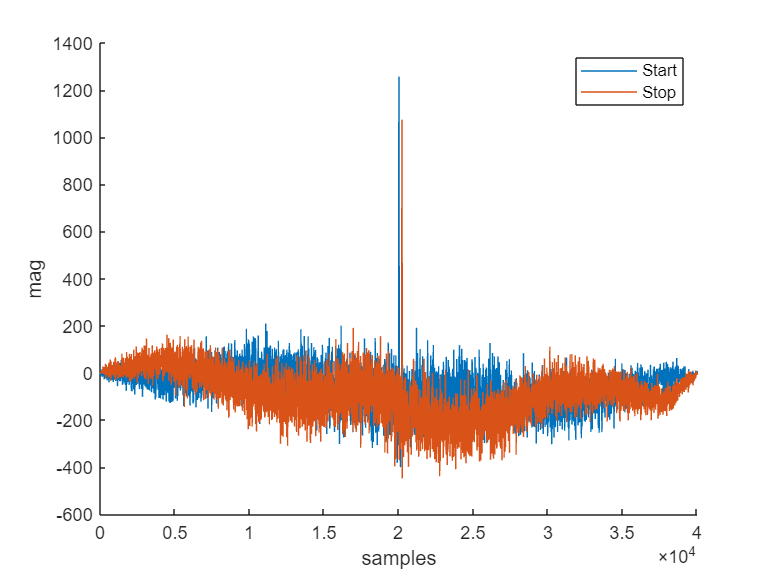

a =         -0.500244548598915         -1.00025473378575         -1.50068469450297         -2.00038395105445         -2.50132342469248         -3.00017359538526         -3.50269008099016         -4.00204332964951         -4.50372226366972          -5.0055886107747         -5.50226234937196         -6.01282020992809         -6.49518572026808         -7.02941817454678         -7.46925647391805          -8.0954865942631         -7.57660425095438         -6.43313829607577         -5.51210129301209         -4.45149528877828         -3.50014055277862         -2.44454583066168         -1.51394951083648          -0.3784080304335        0.0946609265993146        -0.040912434602606        0.0315419248172908      -0.00886594279369698       0.00596993694687424        0.0168174511780279       -0.0311842864647111        0.0848580505800378        -0.430851058602096         -1.57970116973002         -2.49744025983824         -3.56756774777084         -4.50238300918389         -5.59055562261565        

b =        0.00199184715410598       -0.0027200379851459        0.0098882232530972         0.522511321525108          1.01846421800322          1.52239511054663          2.01953614884102          2.52645803064594          3.01406949396205          3.00292343017207          3.00769016024642          3.00490018070815          3.00670075358504          3.00543906357437          3.00615668758947          3.00562298809944          3.00583682137488          3.00564120908556          3.00562801871625          3.00564349124501          3.00580661019818          3.00547144021666          3.00626262103946           3.0049156180601          3.00725893296162          3.00358644325552          3.00924643963149          3.00025295225729           3.0158882000518          2.97655405120017          1.93518838204266         0.954211205289672       -0.0655064520011249         -1.04822037617959         -2.07698448105749          -3.0255211766063         -3.00851838292074         -2.97920411647298        

[a, b] = PlotCorrDrift(frame_size*20, base_sync_1k, emg_sync_1k)

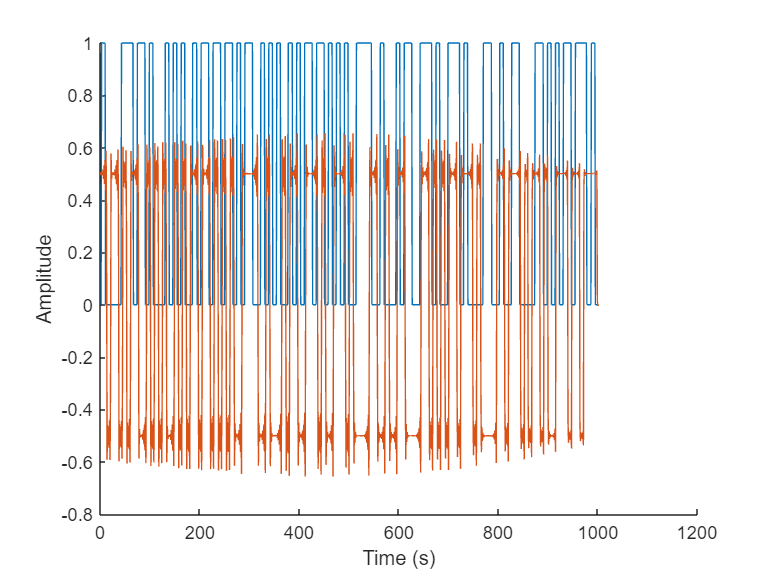


figure;
hold on
plot(base_sync_1k(end - display_points : end), "DisplayName","base");
plot(emg_sync_1k(end - display_points : end), "DisplayName","emg");
% plot(base_sync_1k(1:display_points), "DisplayName","base");
% plot(emg_sync_1k(1:display_points), "DisplayName","emg");
xlabel('Time (s)');
ylabel('Amplitude');
hold off